# “for ... end” structure

## Question

Loop through the matrix and assign each element a new value. Assign 2 on the main diagonal, -1 on the adjescent diagonals and 0 everywhere else. 

Given: nrows=4; nclos=6; A=ones(nrows,nclos);

nrows=4;
nclos=6;
A=ones(nrows,nclos)

A =      1     1     1     1     1     1
     1     1     1     1     1     1
     1     1     1     1     1     1
     1     1     1     1     1     1


for c = 1:nclos
    for r = 1:nrows
        if r == c
            A(r, c) = 2;
        elseif abs(r-c) == 1
            A(r, c) = -1;
        else
            A(r, c) = 0;
        end
    end
end
A

A =      2    -1     0     0     0     0
    -1     2    -1     0     0     0
     0    -1     2    -1     0     0
     0     0    -1     2    -1     0


## example using “any"

limit = 0.75;
A = rand(10,1)

A =     0.1576
    0.9706
    0.9572
    0.4854
    0.8003
    0.1419
    0.4218
    0.9157
    0.7922
    0.9595


if any(A > limit)
    disp( 'There is at least one value above the limit. ')
else
    disp( 'All values are below the limit. ')
end

There is at least one value above the limit. 


## example using “isequal"

### Test Arrays for Equality

Compare arrays using i sequal rather than the == operator to test for equality, because ==

results in an error when the arrays are different sizes.

Create two arrays.

A = ones (3,4)

A =      1     1     1     1
     1     1     1     1
     1     1     1     1


B = rand(3,4)

B =     0.6557    0.9340    0.7431    0.1712
    0.0357    0.6787    0.3922    0.7060
    0.8491    0.7577    0.6555    0.0318


If size(A) and size(B) are the same, concatenate the arrays; otherwise, display a warning

and return an empty array.

if isequal(size(A),size(B))
    C = [A;B] % append
else
    disp( 'A and B are not the same size. ')
    C = [];
end

C =     1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000
    0.6557    0.9340    0.7431    0.1712
    0.0357    0.6787    0.3922    0.7060
    0.8491    0.7577    0.6555    0.0318


## Evaluate multiple condition in an expression 

### Q: Determine if a value falls within a specified range.

x = 10;
minVal = 2;
maxVal = 6;
if (x >= minVal) && (x <= maxVal)
    
    disp('Value within specified range. ')
elseif (x > maxVal)
    disp( 'Value exceeds maximum value. ')
else
    disp( 'Value is below minimum value. ')
end

Value exceeds maximum value. 


### Compare Vectors Containing NaN Values

#### Create three vectors containing NaN values.

A1 = [1 NaN NaN]

A1 =      1   NaN   NaN


A2 = [1 NaN NaN]

A2 =      1   NaN   NaN


A3 = [1 NaN NaN]

A3 =      1   NaN   NaN


Compare the vectors for equality.

tf = isequaln(A1, A2, A3)

tf = logical
   1


The result is logical 1 (true) because isequaln treats the NaN values as equal to each other.

## The “for” loop 

The general form of the for loop is:

for loopvar = range

    action

end

where loopvar is the loop variable, "range" is the range of values through which the loop variable is to iterate, and the action of the loop consists of all state- ments up to the end. Just like with if statements, the action is indented to make it easier to see. The range can be specified using any vector, but normally the easiest way to specify the range of values is to use the colon operator.

## The “for” loop: Question

How could you print this column of integers [using the programming method]:

0

50

100

150

200

for i = 0:50:200
    fprintf("%3d\n",i)
end

  0
 50
100
150
200


## The “for” loop that don’t use iterator

for i = 1:3
    fprintf("I will not chew gum\n")
end

I will not chew gum
I will not chew gum
I will not chew gum


`forecho.m`

% This script loops to repeat the action of prompting the user for a number and echo-printing it
for iv = 1:3
    inputnum = input ( ' Enter a number: ') ;
    fprintf ('You entered : %.1f\n' , inputnum)
end

You entered : 33.0
You entered : 1.1
You entered : 50.0


## Find sum and product 

`sumnnums.m`

% sumnnums calculates the sum of the n numbers entered by the user
n = randi ( [3 10]) ;
runsum = 0 ;
for i = 1:n
    inputnum = input ( 'Enter a number: ') ;
    runsum = runsum + inputnum;
end
fprintf('The sum is %.2f \n' , runsum)

The sum is 890.30 


## Preallocating vector 

`forgenvec.m`

% forgenvec creates a vector of length n It prompts the user and puts n numbers into a vector
n = randi ( [4 8]) ;
numvec = zeros (1, n) ;
for iv = 1:n
    inputnum = input ( ' Enter a number: ' ) ;
    numvec (iv) = inputnum;
end
fprintf ('The vector is: \n')

The vector is: 


disp (numvec)

   44.0000    2.3000    1.1000    3.2000



## “for” loop-subplot 

`subplotex.m`

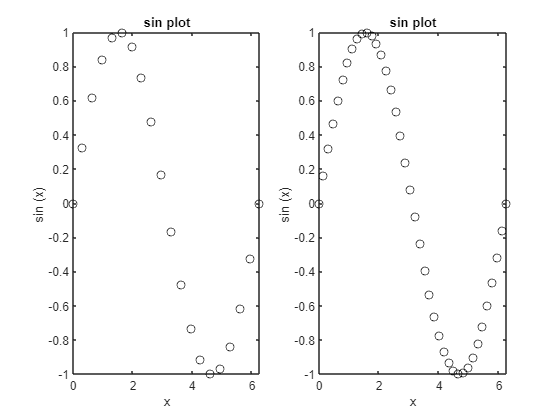

% Demonstrates subplot using a for loop
for i = 1:2  
    x = linspace (0, 2*pi , 20*i) ;
    y = sin (x) ;
    subplot (1, 2, i)
    plot (x, y, 'ko' )
    xlabel ( 'x' )
    ylabel ( 'sin (x) ')
    title ('sin plot')
end

## Nested “for” loop 

- For every row of output:

-     Print the required number of stars 

-     Move the cursor down to the next line (print \n')

`printstars.m`

% Prints a box of stars
% How many will be specified by two variables
% for the number of rows and columns    
rows = 3;
columns = 5;
% loop over the rows
for i=1:rows
% for every row loop to print *'s and then one \n            
    for j=1:columns
        fprintf ('*')
    end
    fprintf ('\n')
end

*****

*****

*****

`printtristars.m`

% Prints a triangle of stars
% How many will be specified by a variable
% for the number of rows    
rows = 3 ;
for i=1:rows
%inner loop just iterates to the value of i
    for j=1:i    
        fprintf ( '*' )
    end
    fprintf ( ' \n')
end

*

**

***

`printloopvars . m`

% Displays the loop variables
for i = 1:3
    for j = 1:2   
        fprintf ('i=%d,j=%d\n', i, j)
    end
    fprintf (' \n' )
end

i=1,j=1
i=1,j=2


i=2,j=1
i=2,j=2


i=3,j=1
i=3,j=2


`multtable. m`

% function outmat = multtable (rows, columns)
% % multtable returns a matrix which is a
% % multiplication table
% % Format : multtable (nRows, nColumns)
% % Preallocate the matrix
% outmat = zeros (rows , columns) ;
% for i = 1 : rows  
%     for j = 1: columns
%         outmat (i , j) = i*j ;
%     end
% end
% end

### Output

multtable(3,5)

ans =

     1     2     3     4     5

     2     4     6     8    10

     3     6     9    12    15

`createmulttab. m`

% Prompt the user for rows and columns and create a multiplication table to store in a file "mymulttable. dat"
num_rows = input ( 'Enter the number of rows : ' ) ;
num_cols = input ( 'Enter the number of columns: ' ) ;
multmatrix = multtable (num_rows, num_cols) ;
save mymulttable.dat multmatrix -ascii

### Output

Enter the number of rows : 6

Enter the number of columns: 4

load mymulttable.dat

mymulttable

mymulttable =

     1     2     3     4

     2     4     6     8

     3     6     9    12

     4     8    12    16

     5    10    15    20

     6    12    18    24